clear 

FileTable = [
'01_01.mat';
'01_02.mat';
'02_01.mat';
'03_01.mat';
'04_01.mat';
'05_01.mat';
'06_01.mat';
'07_01.mat';
'08_01.mat';
'09_01.mat';
'10_01.mat';
'12_01.mat';
'13_01.mat';
'14_01.mat';
'15_01.mat';
'17_01.mat';
'18_01.mat';
'19_01.mat';
'20_01.mat';
'21_01.mat';
'22_01.mat';
'23_01.mat';
'24_01.mat';
'25_01.mat';
'26_01.mat';
'27_01.mat';
'28_01.mat';
'28_02.mat';
'29_01.mat';
'30_01.mat';
'32_01.mat';
'33_01.mat';
'34_01.mat';
'35_01.mat';
];
Nfile = size(FileTable,1); 

Ntype  = 4;
Nvalue = 9;
AnalysisData = zeros(Nfile*Ntype,Nvalue);

for iFile = 1:Nfile
    FileName = FileTable(iFile,:);
    % Point Num Aver Median Std Max Min CI_Upper CI_lower
    AnalysisData((iFile - 1) * Ntype + 1: iFile * Ntype,:) = Analysis(FileName);
end

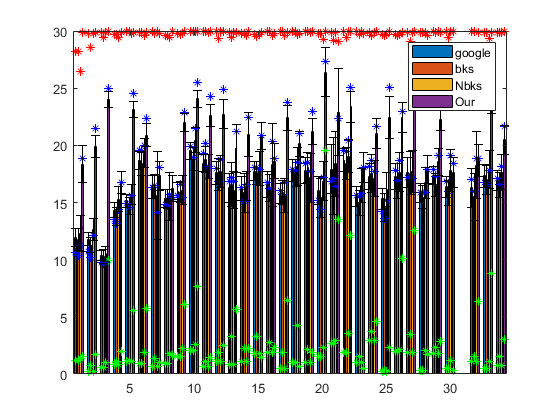

% Point Num Aver Median Std Max Min CI_Upper CI_lower
jIndex = {1 2 3 4 5 6 7 8 9 10 11};
[jPoint, jNum, jAver, jMed, jStd, jMax, jMin, jCI_Upper, jCI_lower] = jIndex{:};

x=1:Nfile;
figure
b = bar([1:Nfile],reshape(AnalysisData(:,jAver),Ntype,[])');
xbar = [b(1).XEndPoints' b(2).XEndPoints' b(3).XEndPoints' b(4).XEndPoints'];
hold on

p1=plot(xbar, reshape(AnalysisData(:,jMax),Ntype,[])','r*');
p2=plot(xbar, reshape(AnalysisData(:,jMin),Ntype,[])','g*');
p3=plot(xbar, reshape(AnalysisData(:,jMed),Ntype,[])','b*');

errorbar(xbar,reshape(AnalysisData(:,jAver),Ntype,[])', ...
    reshape(AnalysisData(:,jCI_lower),Ntype,[])' - reshape(AnalysisData(:,jAver),Ntype,[])', ...
    reshape(AnalysisData(:,jCI_Upper),Ntype,[])'-reshape(AnalysisData(:,jAver),Ntype,[])',...
    'black','Linestyle', 'None');
legend([b(1) b(2) b(3) b(4)],{'google','bks','Nbks','Our'});
% legend(p2,'Max');

hold off